% 定义预设点位
JointPos = [0, 0, -15000000, -10000000, 0;  % IdlePos
    0, -72195, 5174842, -6912012, 0; % ChangeJawPos
    0, -72195, -15000000, -6912012, 0; % PreChangeJawPos
    0, 8673000, 4000000, -10000000, 0; % FetchRingPos
    0, 8673000, -15000000, -10000000, 0; % PreFetchRingPos
    9000, 15686500, -16819200, -5759600, -10; % AssemblePos1
    6000, -8027000, -15911400, 1783100, 0; % AssemblePos2
    0, 0, 7004200, 15275000, 0]; % AssemblePos3

% q_ij 表示第j个关节的第i个路径点
Q = [JointPos(1,:);
    JointPos(3,:);
    JointPos(2,:)];

% syms t0 t1 t2;
% syms q0 q1 q2;
q0 = 0;
q1 = -7;
q2 = -3;
t0 = 0;
t1 = 1;
t2 = 2;
A = [1 t0 t0^2 t0^3 0 0 0 0;
    1 t1 t1^2 t1^3 0 0 0 0;
    0 1 2*t0 3*t0^2 0 0 0 0;
    0 0 0 0 1 t1 t1^2 t1^3;
    0 0 0 0 1 t2 t2^2 t2^3;
    0 0 0 0 0 1 2*t2 3*t2^2;
    0 1 2*t1 3*t1^2 0 -1 -2*t1 -3*t1^2;
    0 0 2 6*t1 0 0 -2 -6*t1];
b = [q0 q1 0 q1 q2 0 0 0]';
x = A \ b;  % 解得各系数

x =          0
         0
  -18.7500
   11.7500
   22.0000
  -66.0000
   47.2500
  -10.2500


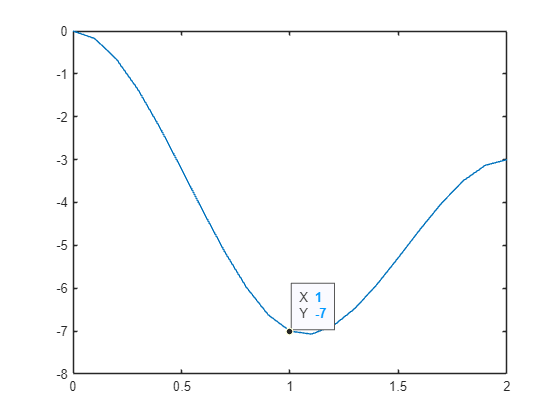


% 绘图 %
ttStep = 0.1;
tt = t0:ttStep:t2;
breakPoint = t1/ttStep;
qq1 = x(1) + x(2).*tt + x(3).*tt.^2 + x(4).*tt.^3;
qq2 = x(5) + x(6).*tt + x(7).*tt.^2 + x(8).*tt.^3;
qq = [qq1(1:breakPoint), qq2(breakPoint+1:length(tt))];

clf;
plot(tt,qq);